mystartdefaults

Question 2

% Energy range and step size
E_min = 0; % in eV
E_max = 0.3; % in eV
deltaE = 0.0005; % in eV
step_size = 0.5;
x1_min = 0;
x1_max = 80;
tau = 1e-9; % 1 ns in seconds
gam=(hbar*2*pi/tau)/qel; % damping factor
recipunit=1.0E+10;
ekinscale=(hbar*recipunit)^2/(2*elm)/qel;
n = (x1_max - x1_min)/step_size;

Create U

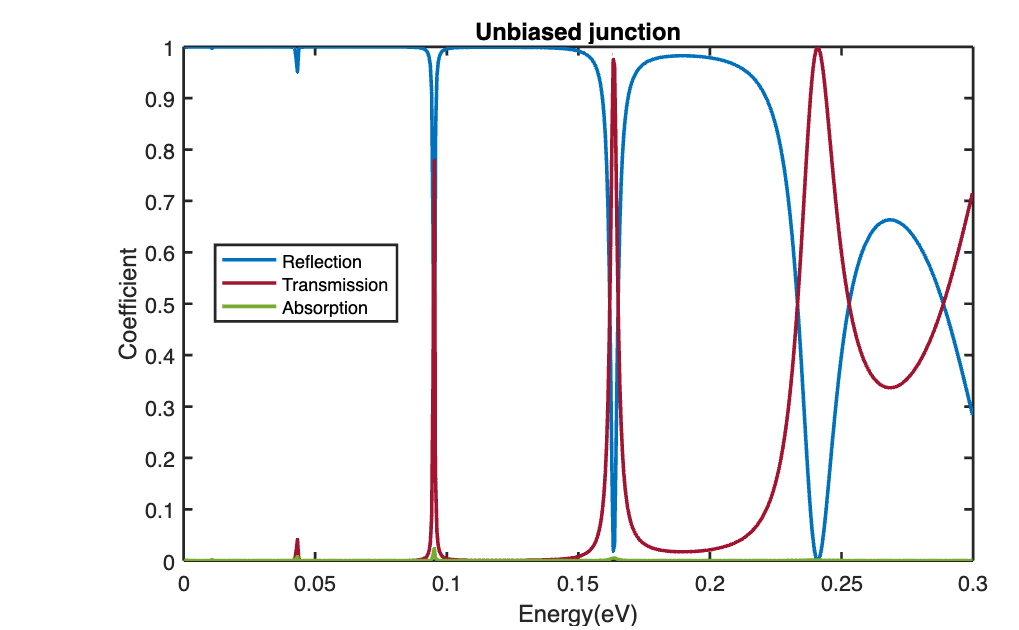

U = zeros(1,n); % Potential barrier
x1 = zeros(1,n);
for i = 1:n
    x1(i) = x1_min + step_size/2 + (i - 1) * step_size;
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.2;
    else
        U(i) = 0;
    end
end
edivide = round((E_max-E_min)/deltaE);
for i = 1:edivide
    E0(i) = deltaE/2 + E_min+(i-1) * deltaE;
end
for i = 1:edivide
    [R_values(i),T_values(i),A_values(i)]=spectra(0,E0(i),gam,x1,U,step_size,ekinscale) ; % the step is set to 0 to look at the constant background case
end
plot(E0, R_values, E0, T_values, E0, A_values, 'LineWidth', 2); % Plotting
xlabel('Energy(eV)');
ylabel('Coefficient');
title('Unbiased junction');
legend('Reflection', 'Transmission', 'Absorption', "FontSize",10, "Location","northwest");
legend_position = [0.25, 0.5, 0.1, 0.1];  % [left, bottom, width, height]
set(gca, 'Position', get(gca, 'Position') + [0.05, 0, 0, 0]);  % Adjust plot position
set(legend, 'Units', 'normalized', 'Position', legend_position);
saveas(gcf, 'unbiased_junction_spectra.png');  % You can specify other file formats like '.jpg', '.pdf', etc.

function [Gf]= Greenf(step,x,xp,E,gam,ekinscale) 
    k0 = sqrt((E + 1i * gam)/ekinscale);
    k1 = sqrt((E + 1i * gam - step)/ekinscale);
    if(x >= 0 && xp >= 0)
        Gf = exp(1i * k1 * abs(x-xp))/(2i * k1) + exp(1i * k1 * (x + xp))*((k1 - k0)/(k1 + k0))/(2i * k1); % Green's function [A.76] for both positions greater than 0
    end

    if (x<0 && xp>=0)
        Gf = exp(-1i * k0 * x + 1i * k1 * xp)/(1i * (k0 + k1)); % Green's function [A.77] for x and xp  on different sides
    end
    if (xp<0 && x>=0)
        Gf = exp(-1i * k0 * xp + 1i * k1 * x)/(1i * (k0 + k1)); % Green's function [A.77] for xp and x  on different sides
    end
end
%% The extra part added to the solution due to the potential 
function[extra]= outside_sol(x,pos,V,dx,phisol,step,E,gam,ekinscale)
    extra=0;
    [~,n]=size(pos);
    for i = 1:n
        extra = extra + Greenf(step,x,pos(i),E,gam,ekinscale) * dx * (V(i)/ekinscale) * phisol(i); %equation [4.36]
    end
end
function[refl,tra,absor] = spectra(step,E,gam,pos,V,dx,ekinscale)
   [~,n]=size(pos);
   k0 = sqrt((E + 1i * gam)/ekinscale);
   k1 = sqrt((E + 1i * gam - step)/ekinscale); 
   tb = 2 * k0/(k0 + k1);
   rb =(k0 - k1)/(k1 + k0);
   W = zeros(n,n);
   for i=1:n
    phi0k(i)=tb * exp(1i * k1 * pos(i));% Function to the right of the step [A.65]
    W(i,i) = dx * V(i)/ekinscale; % Equation[4.39]
    for j=1:n
        G0(i,j)= Greenf(step,pos(i),pos(j),E,gam,ekinscale); %Equation [4.39]
    end
   end
   T = eye(n)- G0 * W;
   phisol = T \ (phi0k.'); % Solution inside the perturbated region [4.51]
   
   phirefl = rb * exp(-1i * k0 * (pos(1)-1)) + outside_sol(pos(1) - 1,pos,V,dx,phisol,step,E,gam,ekinscale); %The first part comes from a pre-existing reflection in equation [A.65]
   phitrans = tb * exp(1i * k1 * (pos(n)+1)) + outside_sol(pos(n) + 1,pos,V,dx,phisol,step,E,gam,ekinscale); %The first part comes from an already exinsting transmission in equation [A.65]
   
   tra = (real(k1)/real(k0)) * abs(phitrans)^2;
   refl = (abs(phirefl/(exp(1i * k0 * (pos(1)-1)))))^2; %comparing the reflected part with just an incoming wave
   absor = 1 - (refl + tra);
end